base_curve_l = 0.6893;
base_curve_curvature = 1.8039;

N_segs = 5;
g_circ_right = zeros(3, 5);
g_circ_right(1, :) = base_curve_l;
g_circ_right(3, :) = base_curve_curvature;

N_arms = 20;
rhos_outer = linspace(0.015, 0.10, N_arms);
rho_inner = 0.01;

l_0 = 0.65;

arms = ArmSeries.empty(0, N_arms);
for i = 1 : N_arms
    arm_i = ArmSeriesFactory.constant_2d_antagonist_arm(N_segs, rho_inner, rhos_outer(i), l_0);
    %arm_i.set_mechanics(GinaMuscleMechanics(l_0), [2, 3]);
    %arm_i.set_mechanics(BasicBellowMechanics(l_0), [1, 4]);
    arm_i.g_circ_right = g_circ_right;
    arms(i) = arm_i;
end

In theory, if our actuator-force surface plots are "realistic", we may then be able to design a manipulator based on an assumed choice of actuator. 

%% Compute actuator force surfaces using minimum-norm least squares
% For each arm's each segment, solve A_i*f_i = -Q_i for f_i, where A_i is the segment
% geometry matrix, q_i is the external reaction induced at the point, and f_i
% is that segment's actuator forces.

Q = [0; -10; 0];
ext_rxns = arms(1).calc_external_reaction(Q);

cell_forces = cell(1, N_arms);
for i = 1 : N_arms
    arm_i = arms(i);
    forces_i = zeros(arm_i.N_rods, N_segs);

    for j = 1 : N_segs
        forces_i(:, j) = lsqminnorm(arm_i.segments(j).mat_A, -ext_rxns(:, j));
    end
    cell_forces{i} = forces_i;
end
mat_forces = cat(3, cell_forces{:});

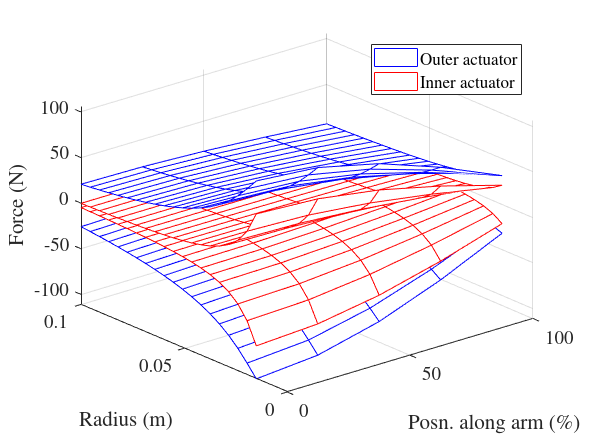

axes(figure(), "FontName", "Times", "FontSize", 14)
s = linspace(0, 1, N_segs);
[S, R] = meshgrid(s, rhos_outer);
hold on

colors = ['b', 'r', 'r', 'b'];
for i = 1 : arms(1).N_rods
    F_i = reshape(mat_forces(i, :, :), N_segs, N_arms)';
    mesh(S * 100, R, F_i, "edgecolor", colors(i));
end

xlabel("Posn. along arm (%)");
ylabel("Radius (m)");
zlabel("Force (N)")
legend(["Outer actuator", "Inner actuator"])
view(-40, 30)
grid on

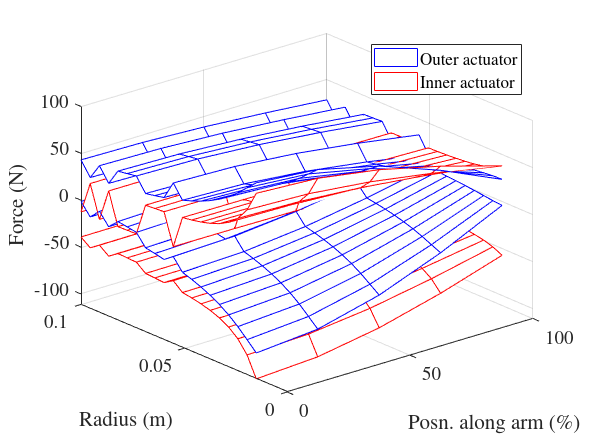

n1 =-20;
n2 =45;

%% Now we try to get a more realistic actuator force plot by looking for other solutions within the valid actuator-force space
mat_forces = nullspace_surf_plot([n1; n2], arms, N_arms, N_segs, rhos_outer, rho_inner);

function mat_forces = nullspace_surf_plot(n, arms, N_arms, N_segs, rhos_outer, rho_inner)
    Q = [0; -10; 0];
    ext_rxns = arms(1).calc_external_reaction(Q);
    int_rxns = -ext_rxns;
    
    cell_forces = cell(1, N_arms);
    for i = 1 : N_arms
        arm_i = arms(i);
        forces_i = zeros(arm_i.N_rods, N_segs);
    
        for j = 1 : N_segs%
            % Instead of lsqminnorm, we will explicitly use the null-space of
            % the pseudoinverse here.
            A_ij = arm_i.segments(j).mat_A;
            soln_space_point = n;
            forces_i(:, j) = null(A_ij) * soln_space_point + pinv(A_ij) * int_rxns(:, j);
            %forces_i(:, j) = lsqminnorm(arm_i.segments(j).mat_A, -ext_rxns(:, j));
        end
        cell_forces{i} = forces_i;
    end
    mat_forces = cat(3, cell_forces{:});
    
    axes(figure(), "FontName", "Times", "FontSize", 14)
    s = linspace(0, 1, N_segs);
    [S, R] = meshgrid(s, rhos_outer);
    hold on
    
    colors = ['b', 'r', 'r', 'b'];
    for i = 1 : arms(1).N_rods
        F_i = reshape(mat_forces(i, :, :), N_segs, N_arms)';
        mesh(S * 100, R, F_i, "edgecolor", colors(i));
    end
    
    xlabel("Posn. along arm (%)");
    ylabel("Radius (m)");
    zlabel("Force (N)")
    legend(["Outer actuator", "Inner actuator"])
    view(-40, 30)
    grid on
end